
%% Case 07 - Stage 1: DSP analysis of one ESC-50 recording
clearvars -except T;
close all; clc;

% Find the audio folder relative to MATLAB's current folder
if isfolder("audio")
    audioFolder = "audio";
elseif isfolder(fullfile("..","audio"))
    audioFolder = fullfile("..","audio");
else
    error("Cannot find the audio folder. Navigate to ESC-50-master or its meta folder.");
end

% Load metadata if it is not already in the workspace
if ~exist("T","var") || ~istable(T)
    if isfile(fullfile("meta","esc50.csv"))
        T = readtable(fullfile("meta","esc50.csv"));
    else
        T = readtable("esc50.csv");
    end
end

% Choose the first available recording
filename = string(T.filename(1));
audioPath = fullfile(audioFolder, filename);

[x, Fs] = audioread(audioPath);

% Convert to mono if the recording has multiple channels
if size(x,2) > 1
    x = mean(x,2);
end

% Time axis and basic signal information
t = (0:length(x)-1)/Fs;
fprintf("File: %s\n", filename);

File: 1-100032-A-0.wav


fprintf("Sample rate: %d Hz\n", Fs);

Sample rate: 44100 Hz


fprintf("Duration: %.3f seconds\n", length(x)/Fs);

Duration: 5.000 seconds


fprintf("Samples: %d\n", length(x));

Samples: 220500


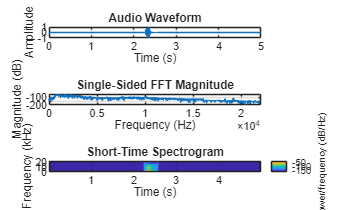


% Figure 1: waveform, FFT magnitude, spectrogram
figure("Name","ESC-50 DSP Analysis","Color","w");
tiledlayout(3,1);

nexttile;
plot(t,x);
xlabel("Time (s)");
ylabel("Amplitude");
title("Audio Waveform");
grid on;

nexttile;
NFFT = 2^nextpow2(length(x));
X = fft(x.*hann(length(x)),NFFT);
f = (0:NFFT/2)*Fs/NFFT;
mag = abs(X(1:NFFT/2+1))/length(x);
plot(f,20*log10(mag+eps));
xlabel("Frequency (Hz)");
ylabel("Magnitude (dB)");
title("Single-Sided FFT Magnitude");
grid on;
xlim([0 Fs/2]);

nexttile;
spectrogram(x,hann(512,"periodic"),384,1024,Fs,"yaxis");
title("Short-Time Spectrogram");

% Save the figure and metadata
if ~isfolder("outputs")
    mkdir("outputs");
end
saveas(gcf,fullfile("outputs","stage1_dsp_analysis.png"));


fprintf("DSP plots saved to outputs/stage1_dsp_analysis.png\n");

DSP plots saved to outputs/stage1_dsp_analysis.png
